# CP241 Lab Assignment - 2

#### September 1, 2023

- `Submission via Teams`*: *`Assignments will be allocated to you via the Teams “``Assignments``” feature. You will have to upload your answer sheet via the same feature in Teams.`  `Answer sheets sent via e-mail will not be considered.`

- `File Logistics:` `Write only the code in .mlx (MATLAB Livescript) with name ”LA_2_<YOUR SERIAL NUMBER>” and submit in Teams. `

- `Note your ``serial number`` is ``last five digits`

- `Warning: ``Don't forget to ``turn in your assignment`` after you have attached your solution`

- `Warning: Attach only live scripts when submitting the assignments.`

`Due Data: 7`` September, 2023                                                                                                                                     ``Maximum Marks:` `20`

## `Question-1`

`Start with the cart pendulum model derived in class and simulate the motion for a time span of `$\left\lbrack \begin{array}{cc}
0 & 50
\end{array}\right\rbrack$` seconds, with initial condition: `$\mathit{\mathbf{x}}=0,\;\dot{\mathit{\mathbf{x}}} =0,\;\theta =\pi \;,\dot{\theta} =0$

`Take the following parameters:`

- `M = mass of the cart = 5 kg`

- `m = mass of the pendulum = 1 kg`

- `L = Length of the pendulum = 2 m`

- `b = friction coefficient = 10 `$\frac{N}{{\textrm{ms}}^{-1} }$

- `g = acceleration due to gravity = `$9\ldotp 8\;\frac{m}{s^2 }$

`Take the following piece-wise defined control input based on your ``serial no``. (For example if your serial no. is ``22896``):`


$$u(t) = 
\begin{cases}
-2\theta \text{ (1st digit)}, &0 \leq t < 10\\
-2\theta \text{ (2nd digit)}, &10 \leq t < 20\\
-8\theta \text{ (3rd digit)}, &20 \leq t < 30\\
-9\theta \text{ (4th digit)}, &30 \leq t < 40\\
-6\theta \text{ (last digit)}, &40 \leq t \leq 50\\
\end{cases}$$


`Use the ``ode45`` to solve the system ode for the above control input and answer the following questions`

- `Plot the conrtol input as a function of time.  [10 marks]`

- `Plot `$x\left(t\right)$` and `$\theta \left(t\right)$` as a function of time.        [10 marks]`

- `Simulate the motion of the system using the ``plotcartpend.m*`` function (No need to submit)`

`* can be downloaded from `[`https://github.com/FocasLab/CP-241-Applied-linear-and-non-linear-control.git`](https://github.com/FocasLab/CP-241-Applied-linear-and-non-linear-control.git) 

## Your main code starts from here

clear all;
clc
close all;

%intial value
x_0 = [0 0 pi 0]';
%time span
tspan = [0, 50];

%ode45 function
[t, X] = ode45(@(t,X) pendcarfun(t,X), tspan, x_0);

### 1.  `Plot the control input as a function of time.  [10 marks]`

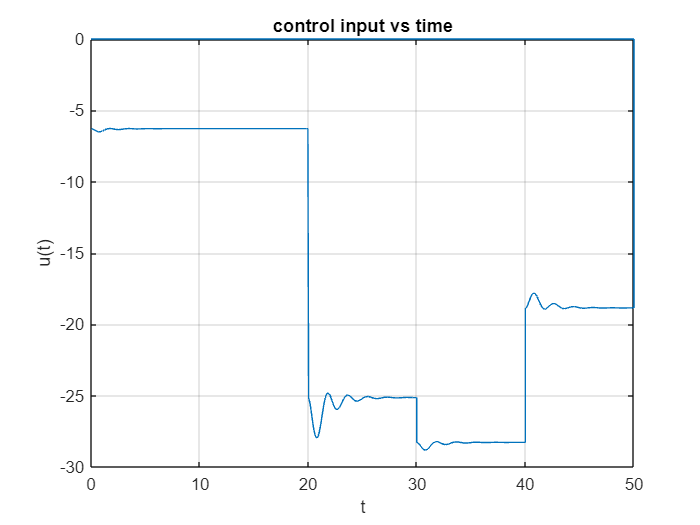

a=length(t);
u = zeros(a);

for i = 1: a
    u(i) = input(t(i), X(i, 3));
end
plot(t, u)

title("control input vs time")
xlabel('t');
ylabel('u(t)');
grid on

### 2a. `Plot the x(t) input as a function of time.  [10 marks]`

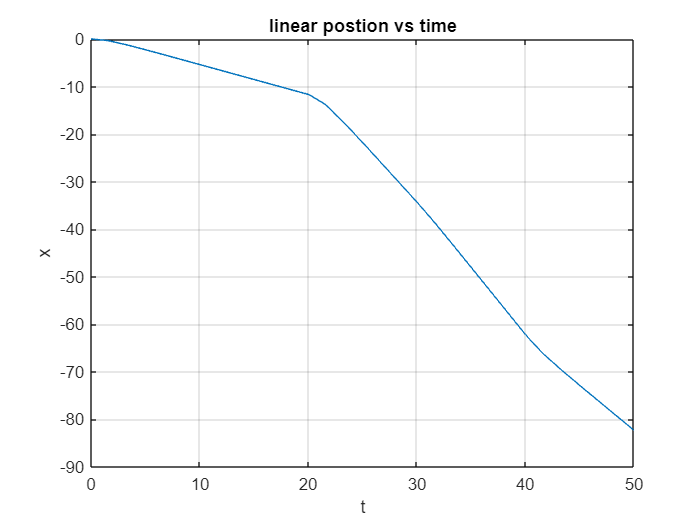

plot(t, X(:, 1))

title("linear postion vs time")
xlabel('t');
ylabel('x')
grid on

`2b.Plot the `$\theta \left(t\right)$` input as a function of time.`

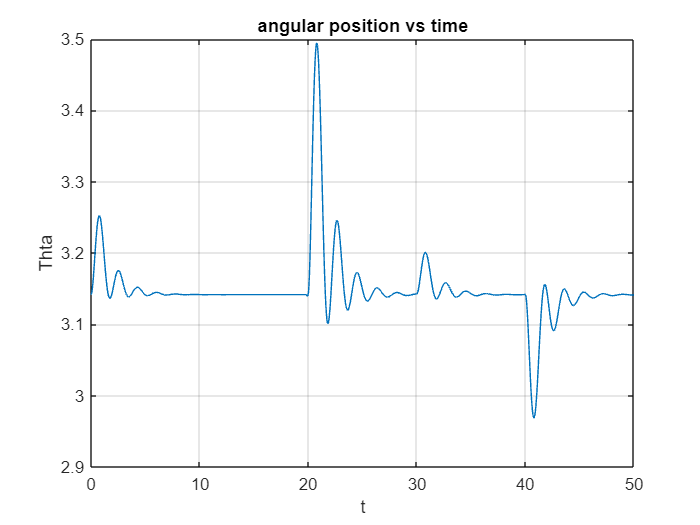

plot(t, X(:, 3))

title("angular position vs time")
xlabel('t');
ylabel('Thta')
grid on

%SR No : 22896
%function defination

%control input

function u_t = input(t, thta)      
      
    u_t = 0;

      if(t >= 0 && t < 10)
          u_t = -2 * thta;
      end

      
      if(t >= 10 && t < 20)
          u_t = -2 * thta;
      end

      
      if(t >= 20 && t < 30)
          u_t = -8 * thta;
      end

      
      if(t >= 30 && t < 40)
          u_t = -9 * thta;
      end

      
      if(t >= 40 && t < 50)
          u_t = -6 * thta;
      end

end 

function x_dot = pendcarfun(t, X)

g = 9.8;
M_cart = 5;
m_pend = 1;
L = 2;
b = 10;

u = input(t, X(3));
M_sys = M_cart + (m_pend * (sin(X(3))^2));


x_dot = zeros(4, 1);

x_dot(1) = X(2);

x_dot(2) = ((g*m_pend*sin(X(3))*cos(X(3))) - (m_pend*L*sin(X(3))*X(4)*X(4)) - ((b * X(2)))/M_sys + u/M_sys);

x_dot(3) = X(4);

x_dot(4) = (cos(X(3))*x_dot(2)) + (g*sin(X(3)))/L;

end